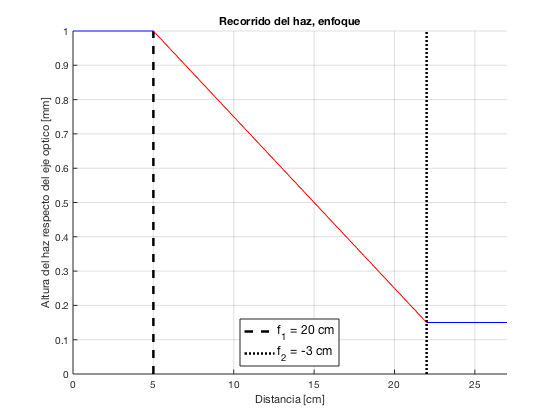

clear all;
close all;

d_0= 5; % en cm
y_e= 1; %1 en mm
theta_e= 0;

%Amplif => f1<0 y f2>0
%Enfoque => f1>0 y f2<0
%+200, +100, +60, +50 y +30 [mm] (plano convexas) 
%-100, −50, −40 y −30 [mm] (plano concavas) 
f_concava = [-10 -5 -4 -3]; %en cm
f_convexa = [20 10 6 5 3];

f1_enf= f_convexa(1); % 10mm=1cm 
f2_enf= f_concava(4);
d = f1_enf + f2_enf; %dist entre lentes
k= 5; %distancia a recorrer luego de la 2da lente

camino_aire_1 = [1 d_0 ; 0 1];
camino_lente_delgada_1 = [1 0 ; -1/f1_enf 1];
camino_aire_2 = [1 d ; 0 1];
camino_lente_delgada_2 = [1 0 ; -1/f2_enf 1];

%camino entre fuente y primera lente
%recorre una distancia d_0
x_d0=[0:1:d_0];
funcion_0 = y_e;

%camino entre primera lente y segunda lente
%recorre una distancia d
[y_s_1,theta_s_1] = trazado_medio(camino_lente_delgada_1,y_e,theta_e);
x_d=[d_0:1:d_0+d];
funcion_1=theta_s_1 * (x_d-d_0) + y_s_1 ; 
%resto d_0 para que me la grafique bien en la interfaz

%camino luego de la segunda lente
%lo hago recorrer k cm mas
y_e_1 = theta_s_1 * (d) + y_s_1;
[y_s_2,theta_s_2] = trazado_medio(camino_lente_delgada_2,y_e_1,theta_s_1);
x_d_2=[d_0+d:1:d_0+d+k];
funcion_2=theta_s_2 * (x_d_2-d_0-d) + y_s_2 ; 
%resto d_0 para que me la grafique bien en la interfaz

%grafico del camino del rayo
figure()
hold on
h(1)=plot([0 d_0],[y_e y_e],'b'); %fuente -> lente f1
h(2)=plot([d_0 d_0],[0 y_e],'--k','LineWidth',2.5); %lente f1
h(3)=plot(x_d,funcion_1,'r'); %lente f1 -> lente f2
h(4)=plot([d_0+d d_0+d],[0 y_e],':k','LineWidth',2.5); %lente f2
h(5)=plot(x_d_2,funcion_2,'b'); %lente f2 -> un poco mas
grid on
axis([0 d_0+d+k 0 y_e]);
title('Recorrido del haz, enfoque');
xlabel('Distancia [cm]');
ylabel('Altura del haz respecto del eje optico [mm]');
lgd = legend(h([2 4]),sprintf('f_1 = %d cm',f1_enf),sprintf('f_2 = %d cm',f2_enf),'location','south','Fontsize',12);
%print('Fig_arreglo_enfoque','-dpng');